signds = imageDatastore("D:\college\FYP\TrafficSignsDataset","IncludeSubfolders",true,"LabelSource","foldernames");
signNames = signds.Labels;
[signTrain,signTest] = splitEachLabel(signds,0.6,"randomized");

% Augmentation
resizeTrainImgs = augmentedImageDatastore([224 224],signTrain);
resizeTestImgs = augmentedImageDatastore([224 224],signTest);

numClasses = numel(categories(signds.Labels));

% Setting Options
opts = trainingOptions("adam","InitialLearnRate",0.001,"MaxEpochs",1,"VerboseFrequency",2);

% Training the network
[signnet,info] = trainNetwork(resizeTrainImgs,ts_network,opts);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:34 |        6.25% |       4.4933 |          0.0010 |
|       1 |           2 |       00:01:10 |       24.22% |       2.1757 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


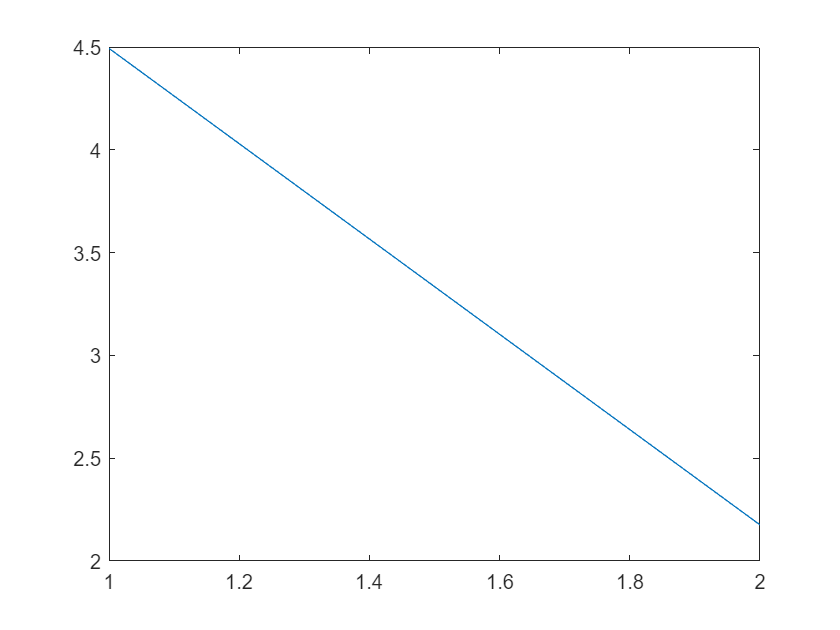


% Evaluating Performance
plot(info.TrainingLoss);

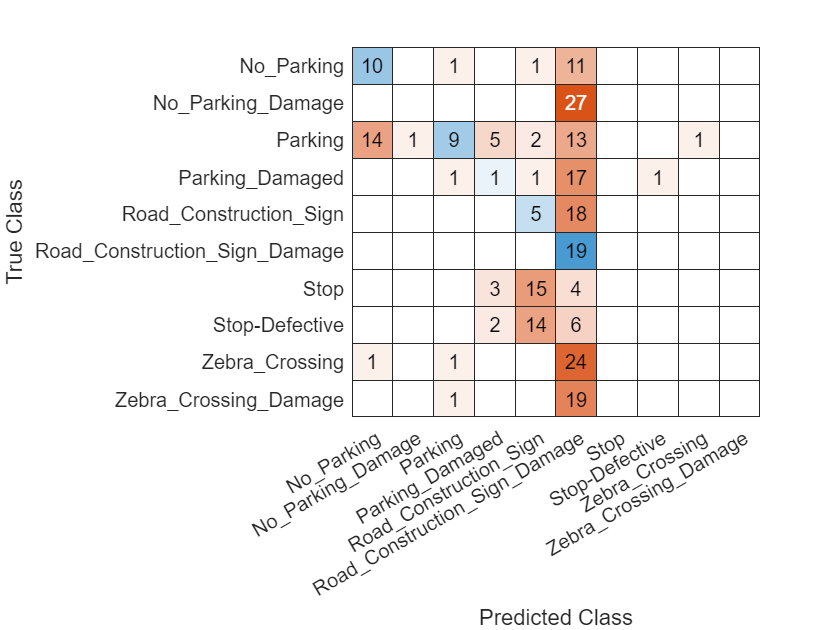

Error using histc
Dimension argument must be a positive integer scalar within indexing range.

Error in categorical/countcats (line 20)
    c = histc(a.codes,1:length(a.categoryNames),dim);



% Prediction
signPrediction = classify(signnet,resizeTestImgs);

signActual = signTest.Labels;

% Comparison
numCorrect = nnz(signPrediction == signActual);
fracCorrect = numCorrect/numel(signPrediction);

% Confusion Chart
confusionchart(signActual,signPrediction);